Filter CF = 3/8 fs

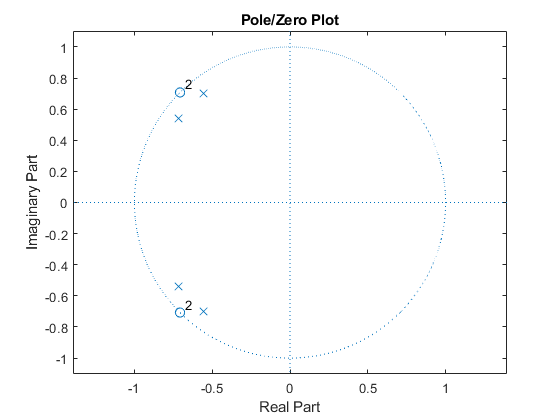

%H(z)
num1 = [1,1.414,1];
num2 = [1,1.414,1];
den1 = [1,1.430,0.8];
den2 = [1,1.114,0.8];

%Convolve
num = conv(num1,num2);
den = conv(den1,den2);

%Calcluates Correct Gain
DesiredGain = 1;
gain = (max(abs(freqz(num, den, 1024))));
k = DesiredGain/gain;
num=num*k;

%Z Plot
figure(5)
zplane(num,den)
title('Pole/Zero Plot')

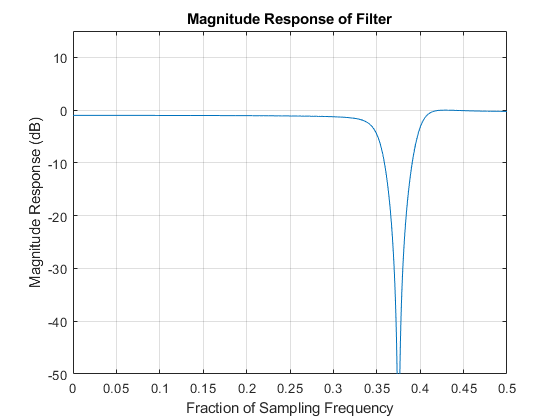


%Plot Response
figure
[H,w]=freqz(num,den,4096);
plot(w/2/pi,20*log10(abs(H)))
title('Magnitude Response of Filter')
ylabel('Magnitude Response (dB)')
xlabel('Fraction of Sampling Frequency')
axis([0 0.5 -50 15]);
grid on